clear;
clc;
close all;

s = tf('s');

%% Parâmetros do conversor Buck
Vs = 50;          % Tensão de entrada [V]
L  = 1.4e-3;      % Indutor [H]
C  = 0.18e-6;     % Capacitor [F]
R  = 41.7;        % Resistência de carga [ohm]
Fs = 50e3;        % Frequência de chaveamento [Hz]
Ts = 1/Fs;


%% Ponto de operação
D = 0.5;          % Duty inicial
delta_d = 0.05;   % Perturbação de duty (+5%)
t_change = 1e-3;  % Instante da alteração [s]


%% =====================================================
% Modelo de pequenos sinais
% ======================================================
rc = 1/(R*C);
lc = 1/(L*C);
l  = 1/L;

% Corrente do indutor / duty
Gid = Vs*l*(s + rc)/(s^2 + rc*s + lc)


Gid =
 
     3.571e04 s + 4.758e09
  ---------------------------
  s^2 + 1.332e05 s + 3.968e09
 
Continuous-time transfer function.



% Tensão de saída / duty
Gvd = Vs*lc/(s^2 + rc*s + lc)


Gvd =
 
           1.984e11
  ---------------------------
  s^2 + 1.332e05 s + 3.968e09
 
Continuous-time transfer function.


Colunas encontradas no arquivo:


    {'time'}    {'V_n002_'}    {'I_L1_'}




Ponto de operação obtido do LTspice:


Vo médio = 24.6253 V


IL médio = 0.5906 A


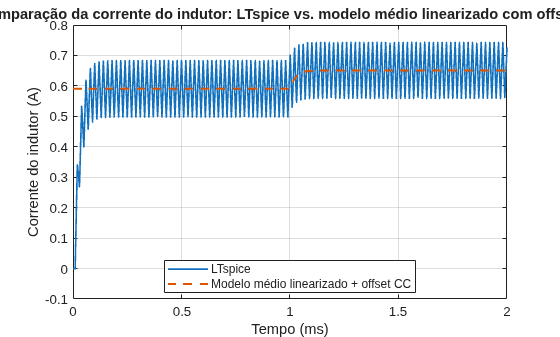

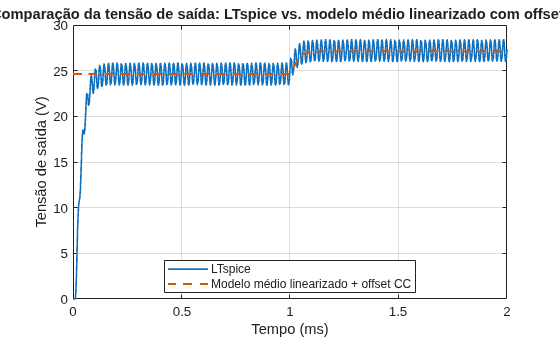



%% Tempo de simulação
t_final = 2e-3;
tempo = linspace(0,t_final,5000);


%% Entrada de pequeno sinal (d_hat)
d = zeros(size(tempo));
d(tempo >= t_change) = delta_d;


%% Resposta do modelo linearizado

[iL_hat,~] = lsim(Gid,d,tempo);
[vO_hat,~] = lsim(Gvd,d,tempo);



%% =====================================================
% Leitura dos dados LTspice
%
% Arquivo:
% time | V(n002) | I(L1)
%
% =====================================================

arquivo = 'buck.txt';


if exist(arquivo,'file')

    dados = readtable(arquivo);

    disp('Colunas encontradas no arquivo:');
    disp(dados.Properties.VariableNames)


    % Dados LTspice
    t_lt = dados.time;
    v_lt = dados.("V_n002_");
    i_lt = dados.("I_L1_");


    %% =================================================
    % Cálculo do ponto de operação pelo LTspice
    % Antes da mudança de duty
    % ==================================================

    t_med_inicio = 0.5e-3;
    t_med_final  = 0.9e-3;

    idx_med = t_lt >= t_med_inicio & t_lt <= t_med_final;


    % Valores médios da onda LTspice
    Vo0 = mean(v_lt(idx_med));
    IL0 = mean(i_lt(idx_med));


    fprintf('\nPonto de operação obtido do LTspice:\n');
    fprintf('Vo médio = %.4f V\n',Vo0);
    fprintf('IL médio = %.4f A\n',IL0);



    %% =================================================
    % Aplicação do offset CC
    % ==================================================

    iL = IL0 + iL_hat;
    vO = Vo0 + vO_hat;



    %% =================================================
    % Comparação corrente do indutor
    % ==================================================
    figure;
    plot(t_lt*1e3,i_lt,'LineWidth',1.2);
    hold on;
    plot(tempo*1e3,iL,'--','LineWidth',1.5);
    grid on;
    xlabel('Tempo (ms)');
    ylabel('Corrente do indutor (A)');
    legend('LTspice',...
           'Modelo médio linearizado + offset CC',...
           'Location','best');
    title('Comparação da corrente do indutor: LTspice vs. modelo médio linearizado com offset CC');


    %% =================================================
    % Comparação tensão de saída
    % ==================================================
    figure;
    plot(t_lt*1e3,v_lt,'LineWidth',1.2);
    hold on;
    plot(tempo*1e3,vO,'--','LineWidth',1.5);
    grid on;
    xlabel('Tempo (ms)');
    ylabel('Tensão de saída (V)');
    legend('LTspice',...
           'Modelo médio linearizado + offset CC',...
           'Location','best');
    title('Comparação da tensão de saída: LTspice vs. modelo médio linearizado com offset CC');

else

    disp('Arquivo buck.txt não encontrado.');

end